## Scatterplot Correlation Whole-brain Coupling SI Social Cognition and Agreeableness

Creation of scatterplot depicting the relationship between whole-brain coupling during the social cognition task (operationalized with SI) and agreeableness. 

Before running this script: 

- run all scripts in HCP Data Prep

**Partial correlations with Agreeableness**

x = [whole_brain_values_HCP_social_table.SI, HCP_behavioral_532.NEOFAC_A]; % change variable in first term to switch between coupling measures
z = [HCP_behavioral_532.Age_in_Yrs, HCP_behavioral_532.gender_num, HCP_behavioral_532.mean_mean_RMS_social, HCP_behavioral_532.Handedness]; % control variables
   
[rho,pval] = partialcorr(x,z)

rho =     1.0000    0.1197
    0.1197    1.0000


pval =          0    0.0059
    0.0059         0


rho =     1.0000    0.0486
    0.0486    1.0000


pval =          0    0.2638
    0.2638         0


ans = 0.0504

**Create Plot for the WAPP Poster **

confounds = [HCP_behavioral_532.Age_in_Yrs, HCP_behavioral_532.gender_num, HCP_behavioral_532.mean_mean_RMS_social, HCP_behavioral_532.Handedness]

confounds =    27.0000         0    0.0543   65.0000
   27.0000    1.0000    0.0617   95.0000
   27.0000         0    0.1102   85.0000
   29.0000         0    0.0495   45.0000
   35.0000    1.0000    0.0807  -75.0000
   26.0000    1.0000    0.0705   10.0000
   30.0000         0    0.0550   50.0000
   23.0000         0    0.0512   80.0000
   30.0000         0    0.1054   70.0000
   34.0000         0    0.1006   45.0000



mdl_brain_values = fitlm(confounds, whole_brain_values_HCP_social_table.SI);
residuals_brain_values = mdl_brain_values.Residuals.Raw

residuals_brain_values =    -0.0198
   -0.0281
   -0.0242
   -0.0255
    0.0426
    0.0036
   -0.0688
    0.0160
   -0.0132
   -0.0505


residuals_brain_values_normalized = normalize(residuals_brain_values)

residuals_brain_values_normalized =    -0.7078
   -1.0046
   -0.8643
   -0.9112
    1.5258
    0.1285
   -2.4605
    0.5708
   -0.4722
   -1.8078



mdl_NEOFAC_A = fitlm(confounds, HCP_behavioral_532.NEOFAC_A);
residuals_NEOFAC_A = mdl_NEOFAC_A.Residuals.Raw

residuals_NEOFAC_A =    -3.6601
    1.9926
   -1.5934
    3.2983
    1.1508
   -4.7795
   -6.8633
    1.6596
    5.1729
    2.9321


residuals_NEOFAC_A_normalized = normalize(residuals_NEOFAC_A)

residuals_NEOFAC_A_normalized =    -0.6666
    0.3629
   -0.2902
    0.6007
    0.2096
   -0.8705
   -1.2500
    0.3023
    0.9421
    0.5340


% scatter(whole_brain_values_HCP_social_table.SI,HCP_behavioral_532.NEOFAC_A)
s = scatter(residuals_brain_values_normalized,residuals_NEOFAC_A_normalized,"black","filled")

s =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×532 double]
              YData: [1×532 double]
              ZData: [1×0 double]
              CData: [0 0 0]

  Show all properties


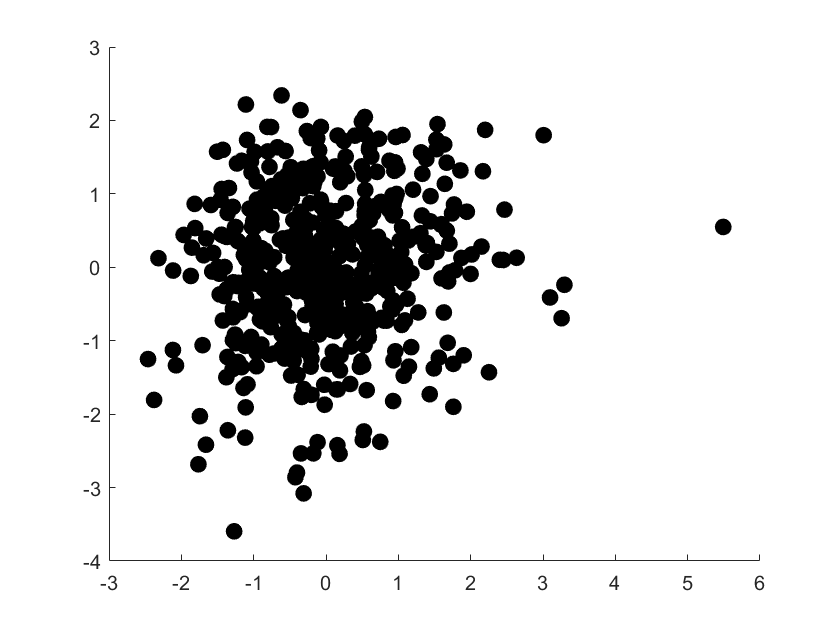

s =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 70
          LineWidth: 0.5000
              XData: [1×532 double]
              YData: [1×532 double]
              ZData: [1×0 double]
              CData: [0 0 0]

  Show all properties


s.SizeData = 70

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_1 = mdl_regress_train_1_emotion_pos_bcs.Residuals.Raw;